**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Autors: P.Ozga & P.Pramod 

### dateset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

### Toolbox: Statistics and Machine Learning & Deep Learning

Clear bufor

close all; clear; clc

## Get the path to the dataset and show first 5 sample

fpath = 'C:/Users/kanal/Desktop/PC-LAP/PC-LAP/Artificial-Neural-Network/wine-quality.csv';%file path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');%correct read file
display(head(fname,5))% show first 5 samples - columns & rows

  5×12 table

    fixed acidity    volatile acidity    citric acid    residual sugar    chlorides    free sulfur dioxide    total sulfur dioxide    density     pH     sulphates    alcohol    quality
    _____________    ________________    ___________    ______________    _________    ___________________    ____________________    _______    ____    _________    _______    _______

           7               0.27             0.36             20.7           0.045              45                     170              1.001  

% display(tail(fname,5)) % Show last 5 samples
% Check each column for non-numerical values
% for i = 1:width(fname)
%     column = fname{:, i}; % Extract the column data
%     if ~isnumeric(column) % Check if the column is not numeric
%         disp(['Column ' fname.Properties.VariableNames{i} ' has non-numerical values']);
%     end
% end

## Normalization all data

X = fname{:, 1:11};  % Features (first 11 columns)
Y = fname{:, 12};    % Quality rating (12th column)
X = (X - min(X)) ./ (max(X) - min(X));  % Min-Max normalization

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## Split the Data into Training and Test Sets:

### about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

cv = cvpartition(size(X, 1), 'HoldOut', 0.3);  %  extract the 70% trening, 30% test indices for cross-validation
% 
X_train = X(training(cv), :);
Y_train = Y(training(cv));
X_test = X(test(cv), :);
Y_test = Y(test(cv));

## Create and Train the MLP (Multilayer Perceptron) Network:

### about `feedforwardnet `function, link: https://ch.mathworks.com/help/deeplearning/ref/feedforwardnet.html

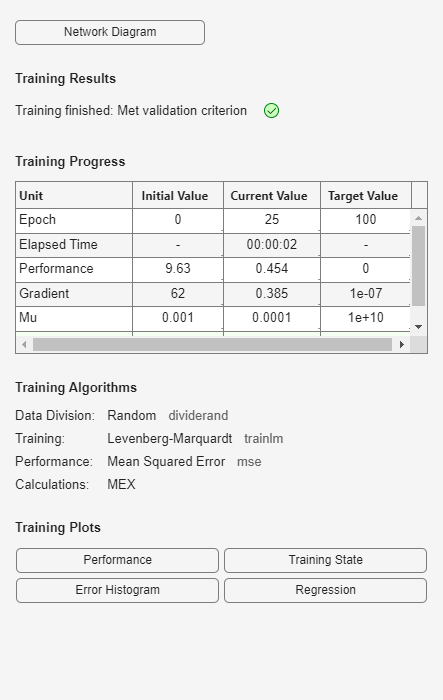

hiddenLayerSize = 12;           %number of neurons, number of feat
net = feedforwardnet(hiddenLayerSize);
net.trainFcn = 'trainlm';       % Levenberg-Marquardt training (+ Hesian information)
net.trainParam.epochs = 100;    % Number of epochs
net.trainParam.show = 50;       % Progress every 50 iterations

[net, tr] = train(net, X_train', Y_train');% Train the network

## Test the Network

net(X_test') % show vector

ans =     5.6793    5.0924    5.7393    5.9637    5.8362    6.4005    5.7955    4.6427    5.6090    5.8210    5.9729    5.3635    5.6398    5.8904    5.2498    5.3737    6.2693    5.1971    5.3737    5.0727    6.7772    5.5685    4.7448    6.6728    6.1462    5.1015    5.1245    5.4753    5.1061    5.1245    5.4892    6.7934    5.7162    4.8385    5.3246    6.6381    6.1345    5.9028    5.1990    4.7168    5.2593    5.9929    6.4561    5.1138    5.9813    6.3711    6.0528    6.2398    6.0907    6.6017


Y_pred = net(X_test');  % Predicting result
Y_pred = Y_pred';       % Transposing result
disp('True quality of wine:'); % from dataset

True quality of wine:


disp(Y_test);

     6
     6
     6
     6
     6
     7
     6
     5
     6
     5
     6
     6
     6
     7
     4
     6
     6
     5
     6
     5
     7
     6
     6
     6
     6
     6
     6
     6
     5
     6
     5
     7
     6
     6
     7
     6
     6
     5
     5
     4
     5
     5
     6
     5
     6
     7
     6
     5
     6
     7
     7
     5
     5
     6
     4
     6
     5
     5
     6
     5
     5
     5
     5
     5
     4
     5
     5
     5
     6
     4
     7
     5
     5
     3
     6
     5
     6
     5
     7
     4
     5
     6
     7
     7
     3
     7
     6
     6
     6
     6
     6
     5
     5
     6
     5
     5
     5
     5
     7
     6
     6
     6
     6
     6
     7
     6
     7
     6
     7
     6
     7
     7
     5
     5
     5
     5
     7
     5
     5
     5
     4
     7
     8
     6
     6
     6
     7
     6
     5
     5
     6
     6
     6
     6
     6
     5
     5
     5
     6
     6
     7
     6
     5

disp('Predicting quality of wine:'); % from net

Predicting quality of wine:


disp(Y_pred);

    5.6793
    5.0924
    5.7393
    5.9637
    5.8362
    6.4005
    5.7955
    4.6427
    5.6090
    5.8210
    5.9729
    5.3635
    5.6398
    5.8904
    5.2498
    5.3737
    6.2693
    5.1971
    5.3737
    5.0727
    6.7772
    5.5685
    4.7448
    6.6728
    6.1462
    5.1015
    5.1245
    5.4753
    5.1061
    5.1245
    5.4892
    6.7934
    5.7162
    4.8385
    5.3246
    6.6381
    6.1345
    5.9028
    5.1990
    4.7168
    5.2593
    5.9929
    6.4561
    5.1138
    5.9813
    6.3711
    6.0528
    6.2398
    6.0907
    6.6017
    6.6017
    5.4420
    5.3060
    5.7394
    5.1009
    6.1070
    6.0223
    5.3752
    5.3457
    5.4637
    5.4927
    5.3629
    5.5912
    6.0099
    4.8681
    5.6798
    5.3592
    6.0309
    4.7641
    4.7711
    6.6114
    5.4034
    5.1585
    6.1172
    5.3322
    5.4395
    5.3322
    4.9788
    6.5850
    5.6870
    5.3083
    5.4390
    5.9211
    5.7860
    3.9986
    6.0838
    5.9874
    5.8791
    5.7996
    5.5214
    6.0861

mse = mean((Y_pred - Y_test).^2);
disp(['Mean square error (MSE): ', num2str(mse)]);

Mean square error (MSE): 0.47243


for classification it is better when you use metrics **accuracy**, **cross-entropy loss** or **F1-score**.

## Evaluate the Results

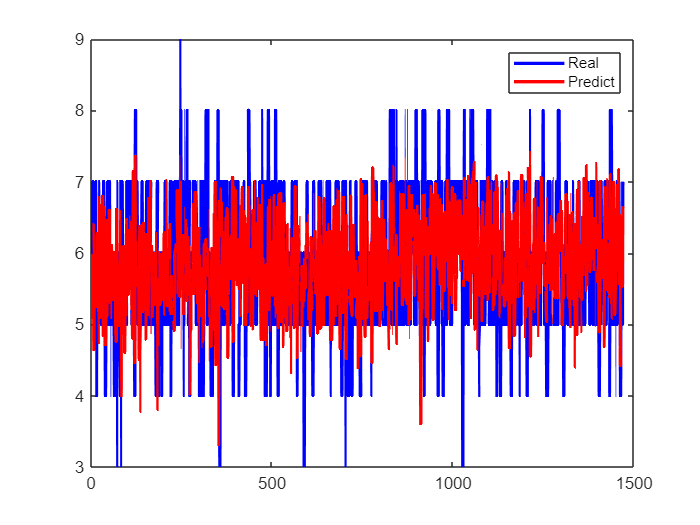

figure;                             % empty graph
plot(Y_test, 'b', 'LineWidth', 2);  % Real Value from dataset
hold on;                            % show the next graph on the same figure
plot(Y_pred, 'r', 'LineWidth', 2);  % Predicted Value from MLP
legend('Real', 'Predict');

% read about overfits, how to avoid and how to make overfits
%It helps to assess whether the model is learning well and whether there is overfitting.

### How to read histogram and different types of histogram in Polish :https://mfiles.pl/pl/index.php/Histogram